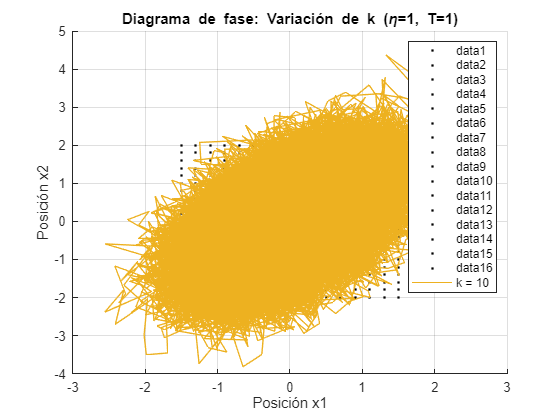

%% Parámetros del sistema
m = 1;
eta = 1;
T1 = 1;
T2 = 3;
k_values = 10;
x1_0 = 0;
x2_0 = 0;
tspan = [0, 1000];
dt = 0.01;
N = tspan(2) / dt;
t = linspace(tspan(1), tspan(2), N);
kb = 1;
x1_eq = 0;
x2_eq = 0;

% Límites automáticos de la malla
step_size = 0.2;
x_min = -1.5; x_max = 1.5;
y_min = -2; y_max = 2;
x_vals = x_min:step_size:x_max;
y_vals = y_min:step_size:y_max;

% Crear malla
[X1, X2] = meshgrid(x_vals, y_vals);

% Inicialización
transitions = containers.Map('KeyType', 'char', 'ValueType', 'any');
time_passes = containers.Map('KeyType', 'char', 'ValueType', 'any');
transition_counts = zeros(length(x_vals), length(y_vals));

x1 = zeros(1, N);
x2 = zeros(1, N);
v1 = zeros(1, N);
v2 = zeros(1, N);
x1(1) = x1_0;
x2(1) = x2_0;

% Diagrama de fase
figure;
hold on;
grid on;
plot(X1, X2, 'k.', 'MarkerSize', 5);

for k = k_values
    sqrt_term1 = sqrt((2 * kb * T1) / eta);
    sqrt_term2 = sqrt((2 * kb * T2) / eta);

    for n = 1:N-1
        dW1 = sqrt(dt) * randn;
        dW2 = sqrt(dt) * randn;
        x1(n+1) = x1(n) + (-2*k * (x1(n)-x1_eq) + k*(x2(n)-x2_eq)) * dt + sqrt_term1*2 * dW1;
        x2(n+1) = x2(n) + (-2*k * (x2(n)-x2_eq) + k*(x1(n)-x1_eq)) * dt + sqrt_term2*2 * dW2;

        current_cell = [floor(x1(n)/step_size), floor(x2(n)/step_size)];
        key = sprintf('%d,%d', current_cell(1), current_cell(2));

        % Guardar el tiempo de paso por la celda
        if isKey(time_passes, key)
            time_passes(key) = [time_passes(key), n];
        else
            time_passes(key) = n;
        end

        % Contar transiciones
        idx_x = find(abs(x_vals - x1(n)) < step_size/2, 1);
        idx_y = find(abs(y_vals - x2(n)) < step_size/2, 1);
        if ~isempty(idx_x) && ~isempty(idx_y)
            transition_counts(idx_x, idx_y) = transition_counts(idx_x, idx_y) + 1;
        end
    end
    plot(x1, x2, 'DisplayName', ['k = ' num2str(k)]);
end

xlabel('Posición x1'); ylabel('Posición x2');
title('Diagrama de fase: Variación de k (\eta=1, T=1)');
legend;
grid on;
hold off;

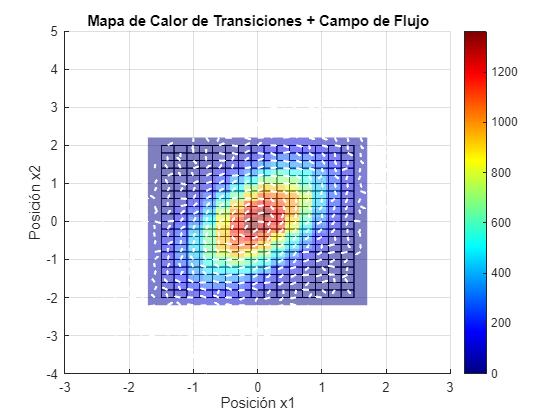

Error using curl (line 54)
The size of X must match the size of U or the number of columns of U.


%% Mapa de calor + Campo de flujo
figure;
hold on;
grid on;

% Dibujar cuadrícula
for i = x_vals
    plot([i i], [y_min y_max], 'k-', 'LineWidth', 0.5);
end
for j = y_vals
    plot([x_min x_max], [j j], 'k-', 'LineWidth', 0.5);
end

% Dibujar el mapa de calor
imagesc([x_min - step_size/2, x_max + step_size/2], ...
        [y_min - step_size/2, y_max + step_size/2], transition_counts');
set(gca, 'YDir', 'normal');
colormap(jet);
colorbar;
alpha(0.5);

% Campo de flujo por desplazamiento real
keys_list = keys(time_passes);
quiver_scale = 0.1;
for i = 1:length(keys_list)
    key = keys_list{i};
    cell_coords = sscanf(key, '%d,%d');
    times = time_passes(key);
    vectors = [];

    for j = 1:length(times)
        idx = times(j);
        while 2 <= idx + 1 <= N
            curr_cell = [floor(x1(idx)/step_size), floor(x2(idx)/step_size)];
            next_cell = [floor(x1(idx+1)/step_size), floor(x2(idx+1)/step_size)];
            if ~isequal(curr_cell, next_cell) && idx > 1
                displacement1 = [x1(idx+1)-x1(idx), x2(idx+1)-x2(idx)];
                displacement2 = [x1(idx)-x1(idx-1), x2(idx)-x2(idx-1)];
                displacement = displacement2+displacement1;
                vectors = [vectors; displacement];
                break;

            else
                displacement2 = [0, 0]; 
                
            end
            idx = idx + 1;
        end
    end

    if ~isempty(vectors)
        mean_vector = mean(vectors, 1);
        if norm(mean_vector) > 0
            mean_vector = mean_vector / norm(mean_vector);
        end
        quiver(cell_coords(1) * step_size, cell_coords(2) * step_size, ...
               mean_vector(1) * quiver_scale, mean_vector(2) * quiver_scale, ...
               'w', 'LineWidth', 1.5, 'MaxHeadSize', 2);
    end
end

xlabel('Posición x1'); ylabel('Posición x2');
title('Mapa de Calor de Transiciones + Campo de Flujo');
hold off;